% k-means
load Salinas_Data
load preprocessed_X
num_features = size(X, 2);
lower_limit = prctile(X, 25)';
upper_limit = prctile(X, 75)';
m = 8;
initial_thetas = lower_limit + (upper_limit - lower_limit)...
                         .* rand(num_features, m);
[~, bel, ~] = k_means(X', initial_thetas);
cl_label = bel;
K = m;
numel(unique(cl_label))

ans = 6

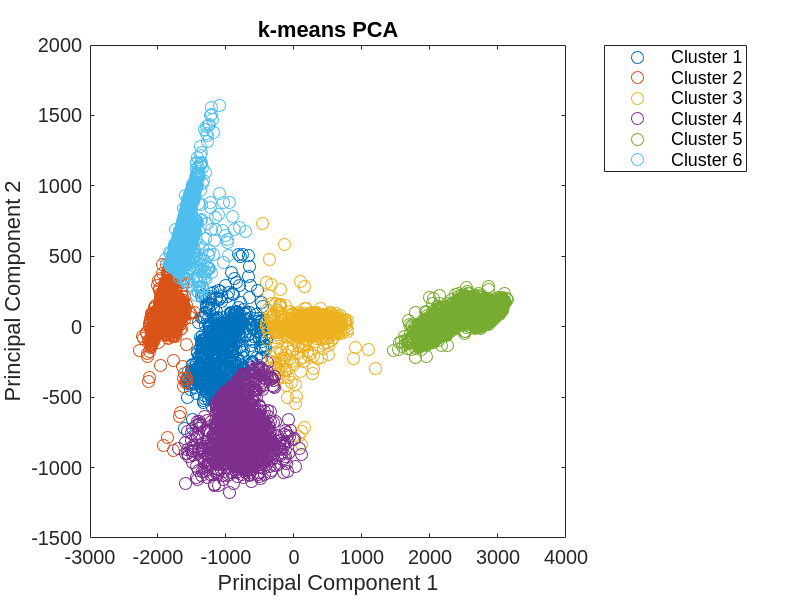

plotPCAClusters(X, cl_label, "k-means PCA");

% fuzzy no preprocess
load Salinas_Data
[p, n, l] = size(Salinas_Image);
X_total = reshape(Salinas_Image, p * n, l);
L = reshape(Salinas_Labels, p * n, 1);
existed_L = (L > 0);
X = X_total(existed_L, :);
num_features = size(X, 2);
m = 8;
seed = 42;
q = 2;
thresh = 0.01;
[U, ~, ~] = fuzzy_c_means(X, m, q, thresh, seed);
[~, cl_label] = max(U, [], 2);
numel(unique(cl_label))

ans = 8

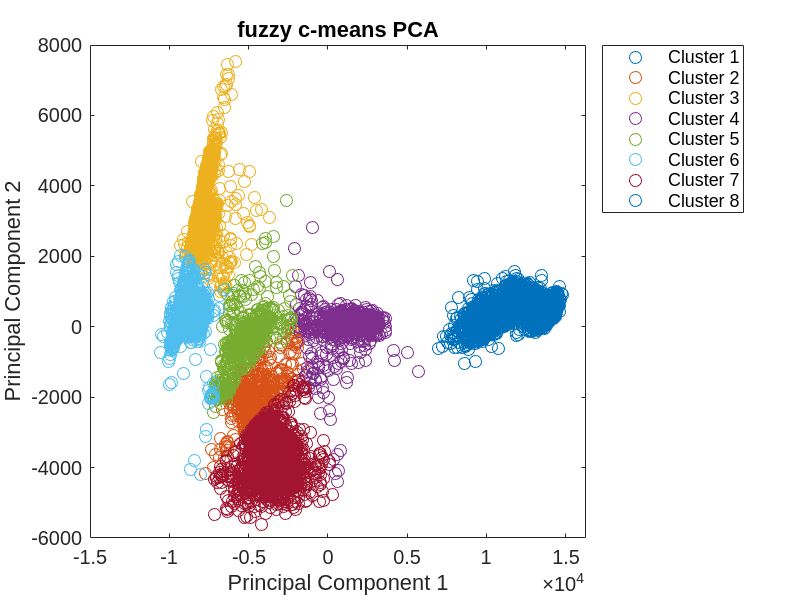

plotPCAClusters(X, cl_label, "fuzzy c-means PCA");

% possibilistic c-means
load Salinas_Data
load preprocessed_X
m = 8;
q = 2;
eta = calc_eta(X', m, q);
seed = 42;
init_proc = 3;
e_thresh = 0.0001;
[U, theta] = possibi(X', m, eta, q, seed, init_proc, e_thresh);
[~, cl_label] = max(U, [], 2);
numel(unique(cl_label))

ans = 4

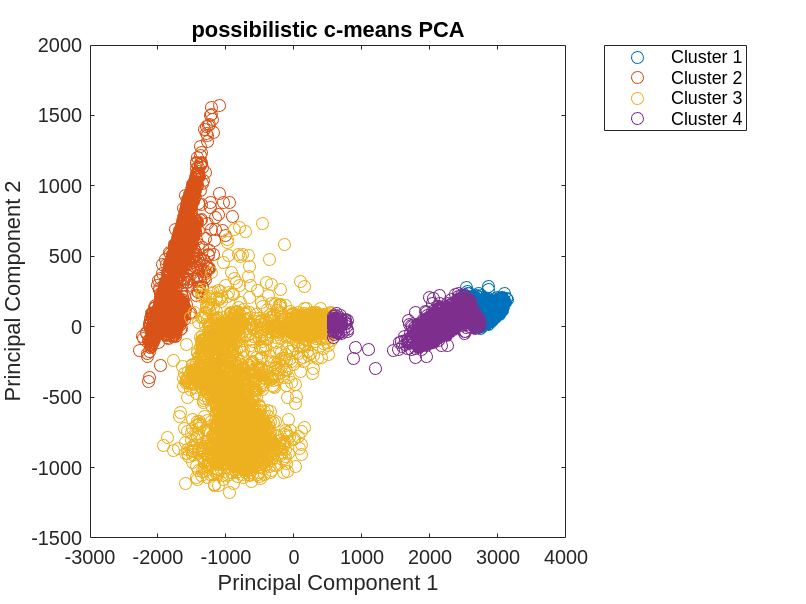

plotPCAClusters(X, cl_label, "possibilistic c-means PCA");

% probabilistic
load Salinas_Data
load preprocessed_X
X = zscore(X);
m = 8;
thresh = 1e-10;
seed = 42;
[~, ~, ~, gamma] = probabi(X, m, thresh, seed);

Iteration: 1	convergence value (e): 9.973600e+01
Iteration: 2	convergence value (e): 1.466605e-13


[~, cl_label] = max(gamma, [], 2);
numel(unique(cl_label))

ans = 7

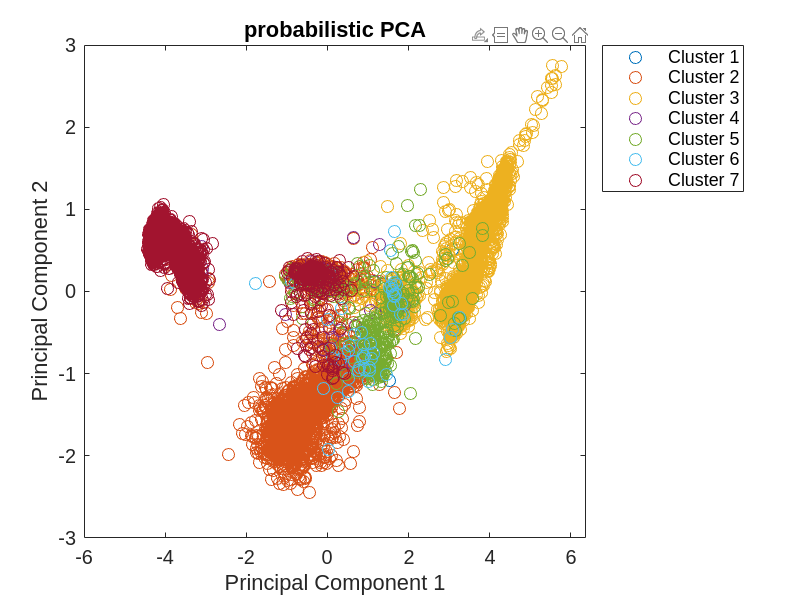

plotPCAClusters(X, cl_label, "probabilistic PCA");

% Complete-Link
load Salinas_Data
load preprocessed_X
X = zscore(X);
Z = linkage(X, 'complete', 'euclidean');
K = 8;
[p,n,l]=size(Salinas_Image);
X_total = reshape(Salinas_Image, p * n, l);
L = reshape(Salinas_Labels, p * n, 1);
existed_L = (L > 0);
X = X_total(existed_L, :);
cl_label = cluster(Z, 'maxclust', K);
numel(unique(cl_label))

ans = 8

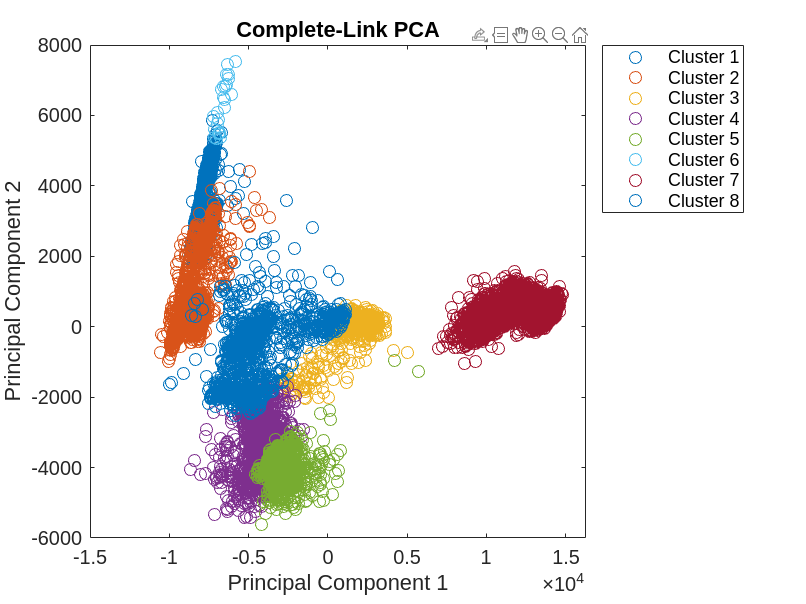

plotPCAClusters(X, cl_label, "Complete-Link PCA");

% WPGMA
load Salinas_Data
load preprocessed_X
X = zscore(X);
Z = linkage(X, 'weighted', 'euclidean');
K = 8;
[p,n,l]=size(Salinas_Image);
X_total = reshape(Salinas_Image, p * n, l);
L = reshape(Salinas_Labels, p * n, 1);
existed_L = (L > 0);
X = X_total(existed_L, :);
cl_label = cluster(Z, 'maxclust', K);
numel(unique(cl_label))

ans = 8

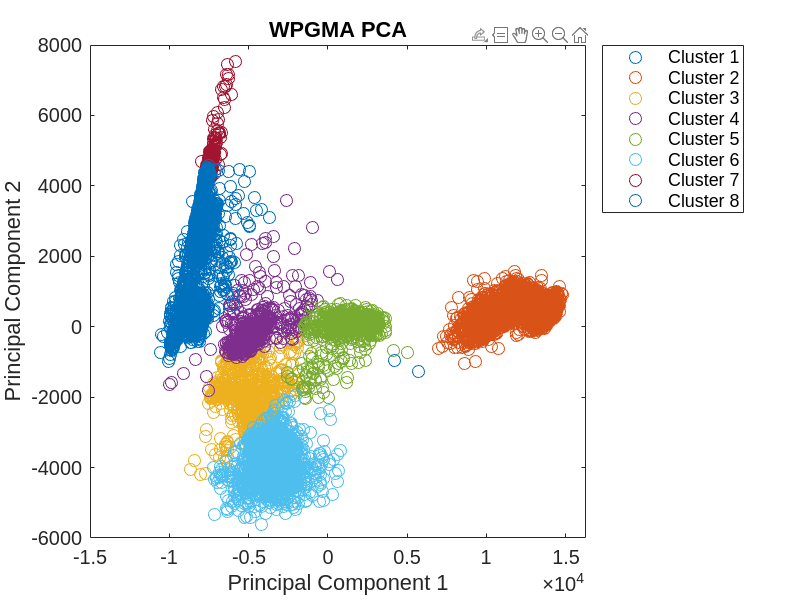

plotPCAClusters(X, cl_label, "WPGMA PCA");

% Ward Clustering
load Salinas_Data
load preprocessed_X
X = zscore(X);
Z = linkage(X, 'ward', 'euclidean');
K = 8;
[p,n,l]=size(Salinas_Image);
X_total = reshape(Salinas_Image, p * n, l);
L = reshape(Salinas_Labels, p * n, 1);
existed_L = (L > 0);
X = X_total(existed_L, :);
cl_label = cluster(Z, 'maxclust', K);
numel(unique(cl_label))

ans = 8

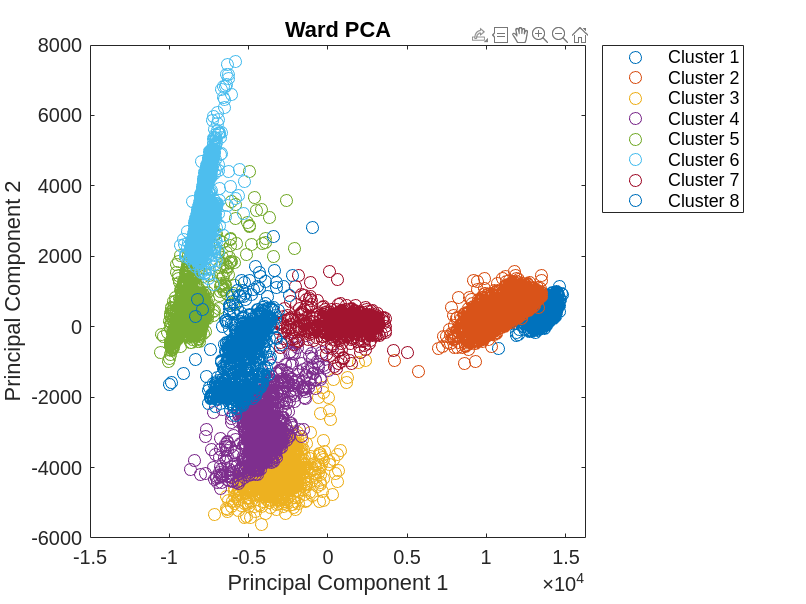

plotPCAClusters(X, cl_label, "Ward PCA");